# **MENENTUKAN LINTASAN ORBIT SATELIT MENGGUNAKAN METODE RUNGE-KUTTA**

**DEKRIPSI MASALAH**

Sebuah satelit diluncurkan ke orbit rendah Bumi dengan posisi awal pada $x_0=7000$ km dan $y_0 = 0$ km. Kecepatan awalnya adalah $vx_0= 0$ km/s dan $vy_0= 7.12$ km/s. Dengan menggunakan metode numerik Runge-Kutta orde ke-4, tentukan posisi dan kecepatan satelit setelah 5000 detik.

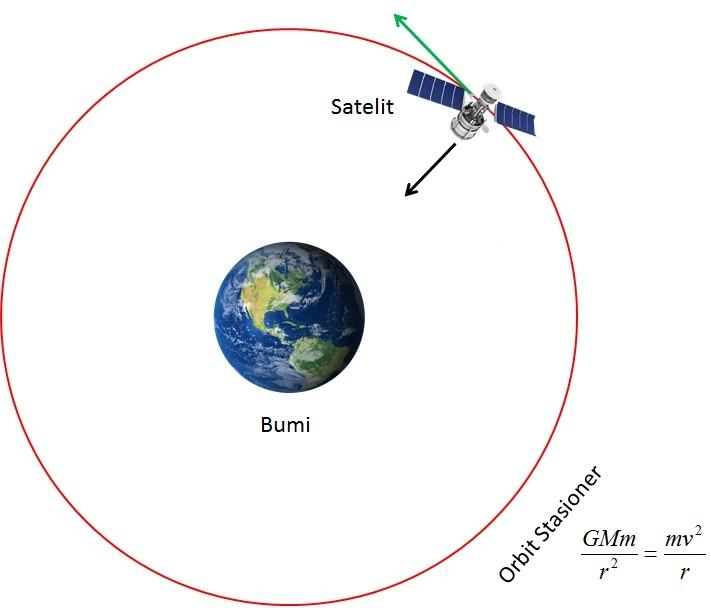

*(Gambar hanya pelengkap)*

**MODEL MATEMATIKA (LaTeX)**

*Rumus Newton Gravitasi*:


$$F = -G\frac{Mm}{r^2}$$


dimana G adalah konstanta gravitasi, M adalah massa bumi, m adalah massa satelit, dan r adalah jarak pusat bumi dengan satelit. Kemudian satelit bergerak dalam dua dimensi maka akan ada x dan y sehingga ada 4 persamaan diferensial:

Posisi x adalah $\frac{dx}{dt} = vx$

Posisi y adalah $\frac{dy}{dt} = vy$

Kecepatan vx adalah $\frac{dvx}{dt} = \frac{GMx}{(x^2+y^2)^{\frac{3}{2}}}$

Kecepatan vy adalah $\frac{dvy}{dt} = \frac{GMy}{(x^2+y^2)^{\frac{3}{2}}}$

*Rumus Runge-Kutta untuk x*:


$$kx_1 = h f_x(t_i , x_i , y_i , vx_i , vy_i )$$



$$kx_2= hf_x(t_i + \frac{h}{2} , x_i + \frac{kx_1}{2} , y_i , vx_i , vy_i )$$



$$kx_3= hf_x(t_i + \frac{h}{2} , x_i + \frac{kx_2}{2} , y_i , vx_i , vy_i )$$



$$kx_4= hf_x(t_i +h , x_i + kx_3  , y_i , vx_i , vy_i )$$



$$x_{(i+1)}= x_i + \frac{1}{6}(kx_1 + 2 kx_2 + 2kx_3 + kx_4)$$


*Rumus Runge-Kutta untuk y*:


$$ky_1 = h f_y(t_i , x_i , y_i , vx_i , vy_i )$$



$$ky_2= hf_y(t_i + \frac{h}{2} , x_i , y_i+ \frac{ky_1}{2} , vx_i , vy_i )$$



$$ky_3= hf_y(t_i + \frac{h}{2} , x_i , y_i+ \frac{ky_2}{2} , vx_i , vy_i )$$



$$ky_4= hf_y(t_i +h , x_i  , y_i+ ky_3  , vx_i , vy_i )$$



$$y_{(i+1)}= y_i + \frac{1}{6}(ky_1 + 2 ky_2 + 2ky_3 + ky_4)$$


*Rumus Runge-Kutta untuk vx*:


$$kvx_1 = h f_{vx}(t_i , x_i , y_i , vx_i , vy_i )$$



$$kvx_2= hf_{vx}(t_i + \frac{h}{2} , x_i , y_i , vx_i + \frac{kvx_1}{2}, vy_i )$$



$$kvx_2= hf_{vx}(t_i + \frac{h}{2} , x_i , y_i , vx_i + \frac{kvx_2}{2}, vy_i )$$



$$kvx_4= hf_{vx}(t_i +h , x_i , y_i , vx_i + kvx_3  , vy_i )$$



$$vx_{(i+1)}= vx_i + \frac{1}{6}(kvx_1 + 2 kvx_2 + 2kvx_3 + kvx_4)$$


*Rumus Runge-Kutta untuk vy*:


$$kvy_1 = h f_{vy}(t_i , x_i , y_i , vx_i , vy_i )$$



$$kvy_2= hf_{vy}(t_i + \frac{h}{2} , x_i , y_i , vx_i , vy_i+ \frac{kvy_1}{2} )$$



$$kvy_3= hf_{vy}(t_i + \frac{h}{2} , x_i , y_i , vx_i , vy_i+ \frac{kvy_2}{2} )$$



$$kvy_4= hf_{vx}(t_i +h , x_i , y_i , vx_i  , vy_i + kvy_3 )$$



$$vy_{(i+1)}= vy_i + \frac{1}{6}(kvy_1 + 2 kvy_2 + 2kvy_3 + kvy_4)$$


**KODE**

% Inisisasi G dan M dahulu
G = 6.67430e-11; % konstanta gravitasi dalam m^3 kg^-1 s^-2
M = 5.972e24; % massa bumi dalam kg

% Input persamaan diferensial untuk gerak satelit
fx = @(t, x, y, vx, vy) vx;
fy = @(t, x, y, vx, vy) vy;
fvx = @(t, x, y, vx, vy) -G*M*x/(sqrt(x^2 + y^2)^3);
fvy = @(t, x, y, vx, vy) -G*M*y/(sqrt(x^2 + y^2)^3);

% Input variabel awal dan parameter simulasi
t0 = 0;
x0 = 7000e3; % posisi awal x dalam meter
y0 = 0; % posisi awal y dalam meter
vx0 = 0; % kecepatan awal vx dalam m/s
vy0 = 7.12e3; % kecepatan awal vy dalam m/s
h = 10; % step-size dalam detik
tn = 5000; % waktu akhir dalam detik

n = round((tn - t0) / h);
t = zeros(1, n + 1);
x = zeros(1, n + 1);
y = zeros(1, n + 1);
vx = zeros(1, n + 1);
vy = zeros(1, n + 1);

% Inisialisasi kondisi awal
t(1) = t0;
x(1) = x0;
y(1) = y0;
vx(1) = vx0;
vy(1) = vy0;

% Runge-Kutta untuk setiap langkah waktu
for i = 1:n
    t(i+1) = t0 + i * h;
    
    % Runge-Kutta untuk x
    k1x = h * fx(t(i), x(i), y(i), vx(i), vy(i));
    k2x = h * fx(t(i) + (h / 2), x(i) + (k1x / 2), y(i), vx(i), vy(i));
    k3x = h * fx(t(i) + (h / 2), x(i) + (k2x / 2), y(i), vx(i), vy(i));
    k4x = h * fx(t(i) + h, x(i) + k3x, y(i), vx(i), vy(i));
    x(i+1) = x(i) + (1 / 6) * (k1x + 2 * k2x + 2 * k3x + k4x);
    
    % Runge-Kutta untuk y
    k1y = h * fy(t(i), x(i), y(i), vx(i), vy(i));
    k2y = h * fy(t(i) + (h / 2), x(i), y(i) + (k1y / 2), vx(i), vy(i));
    k3y = h * fy(t(i) + (h / 2), x(i), y(i) + (k2y / 2), vx(i), vy(i));
    k4y = h * fy(t(i) + h, x(i), y(i) + k3y, vx(i), vy(i));
    y(i+1) = y(i) + (1 / 6) * (k1y + 2 * k2y + 2 * k3y + k4y);
    
    % Runge-Kutta untuk vx
    k1vx = h * fvx(t(i), x(i), y(i), vx(i), vy(i));
    k2vx = h * fvx(t(i) + (h / 2), x(i), y(i), vx(i) + (k1vx / 2), vy(i));
    k3vx = h * fvx(t(i) + (h / 2), x(i), y(i), vx(i) + (k2vx / 2), vy(i));
    k4vx = h * fvx(t(i) + h, x(i), y(i), vx(i) + k3vx, vy(i));
    vx(i+1) = vx(i) + (1 / 6) * (k1vx + 2 * k2vx + 2 * k3vx + k4vx);
    
    % Runge-Kutta untuk vy
    k1vy = h * fvy(t(i), x(i), y(i), vx(i), vy(i));
    k2vy = h * fvy(t(i) + (h / 2), x(i), y(i), vx(i), vy(i) + (k1vy / 2));
    k3vy = h * fvy(t(i) + (h / 2), x(i), y(i), vx(i), vy(i) + (k2vy / 2));
    k4vy = h * fvy(t(i) + h, x(i), y(i), vx(i), vy(i) + k3vy);
    vy(i+1) = vy(i) + (1 / 6) * (k1vy + 2 * k2vy + 2 * k3vy + k4vy);
    
    % Output posisi dan kecepatan untuk setiap langkah waktu
    fprintf('t=%.2f: x=%.4f, y=%.4f, vx=%.4f, vy=%.4f\n', t(i+1), x(i+1), y(i+1), vx(i+1), vy(i+1));
end

t=10.00: x=7000000.0000, y=71200.0000, vx=-81.3447, vy=7120.0000
t=20.00: x=6999186.5527, y=142400.0000, vx=-162.6768, vy=7119.1727
t=30.00: x=6997559.7842, y=213591.7274, vx=-243.9900, vy=7117.5184
t=40.00: x=6995119.8842, y=284766.9114, vx=-325.2778, vy=7115.0372
t=50.00: x=6991867.1058, y=355917.2833, vx=-406.5340, vy=7111.7293
t=60.00: x=6987801.7654, y=427034.5764, vx=-487.7522, vy=7107.5949
t=70.00: x=6982924.2431, y=498110.5257, vx=-568.9261, vy=7102.6343
t=80.00: x=6977234.9825, y=569136.8686, vx=-650.0492, vy=7096.8476
t=90.00: x=6970734.4909, y=640105.3442, vx=-731.1151, vy=7090.2350
t=100.00: x=6963423.3396, y=711007.6938, vx=-812.1176, vy=7082.7967
t=110.00: x=6955302.1634, y=781835.6609, vx=-893.0502, vy=7074.5330
t=120.00: x=6946371.6615, y=852580.9909, vx=-973.9065, vy=7065.4441
t=130.00: x=6936632.5969, y=923235.4315, vx=-1054.6800, vy=7055.5301
t=140.00: x=6926085.7970, y=993790.7326, vx=-1135.3643, vy=7044.7914
t=150.00: x=6914732.1538, y=1064238.6465, vx=-1215.9530, 

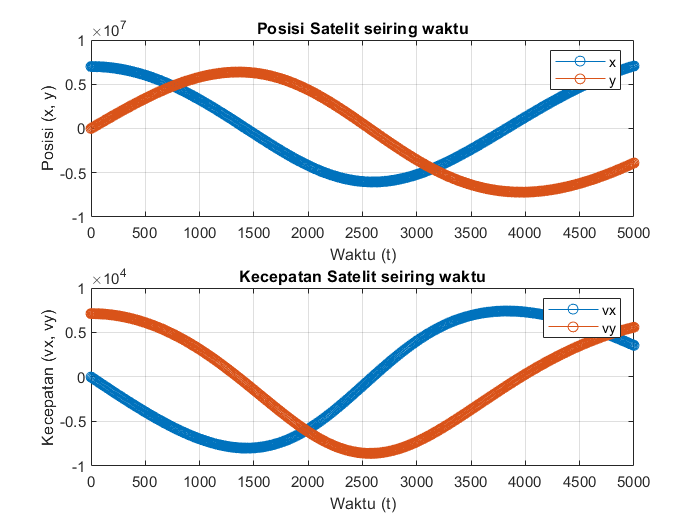


% Plot hasil
figure;
subplot(2, 1, 1);
plot(t, x, '-o', t, y, '-o');
xlabel('Waktu (t)');
ylabel('Posisi (x, y)');
legend('x', 'y');
title('Posisi Satelit seiring waktu');
grid on;

subplot(2, 1, 2);
plot(t, vx, '-o', t, vy, '-o');
xlabel('Waktu (t)');
ylabel('Kecepatan (vx, vy)');
legend('vx', 'vy');
title('Kecepatan Satelit seiring waktu');
grid on;

**HASIL**

Pada permasalahan ini, x dan y adalah koordinat posisi satelit sementara vx dan vy adalah kecepatan satelit serta turunan dari vx dan vy terhadap dt adalah percepatan karena gravitasi. Metode Runge-Kutta orde 4 ini dipakai untuk mendekati solusi dari persamaan diferensial. Metode ini digunakan karena memberikan hasil yang akurat dan stabil. Adapun dari grafik dapat kita simpulkan bahwa

Posisi Satelit seiring waktu:

- Posisi satelit dalam arah x (x) menurun seiring waktu, sedangkan posisi dalam arah y (y) awalnya meningkat.

- Ini menunjukkan bahwa satelit berada dalam orbit elips di sekitar Bumi. Seiring berjalannya waktu, satelit bergerak menjauh dari posisi awalnya (7000 km) sepanjang sumbu x sambil bergerak mengelilingi Bumi.

- Kami telah mengubah t (waktu) menjadi yang lebih banyak dengan nilai step size yang tetap dan mendapati hasil bahwa nantinya x dan y akan melakukan persimpangan kembali.

Kecepatan Satelit seiring waktu:

- Kecepatan dalam arah x (vx) menjadi lebih negatif seiring waktu, menunjukkan bahwa satelit sedang berakselerasi ke arah x negatif.

- Kecepatan dalam arah y (vy) tetap relatif tinggi tetapi menunjukkan variasi sedikit, yang sesuai dengan pola orbit elips di mana kecepatan satelit berubah tergantung pada posisinya di orbit.

Pada akhirnya, saat t = 5000 detik maka posisi-posisinya sesuai pada hasil di samping yaitu posisi x = 7063272.6089 meter, posisi y = -3890703.3702 meter, kecepatan vx = 3553.5409 meter/detik, dan kecepatan vy = 5592.1189 meter/detik.

**LANGKAH-LANGKAH (FLOWCHART)**

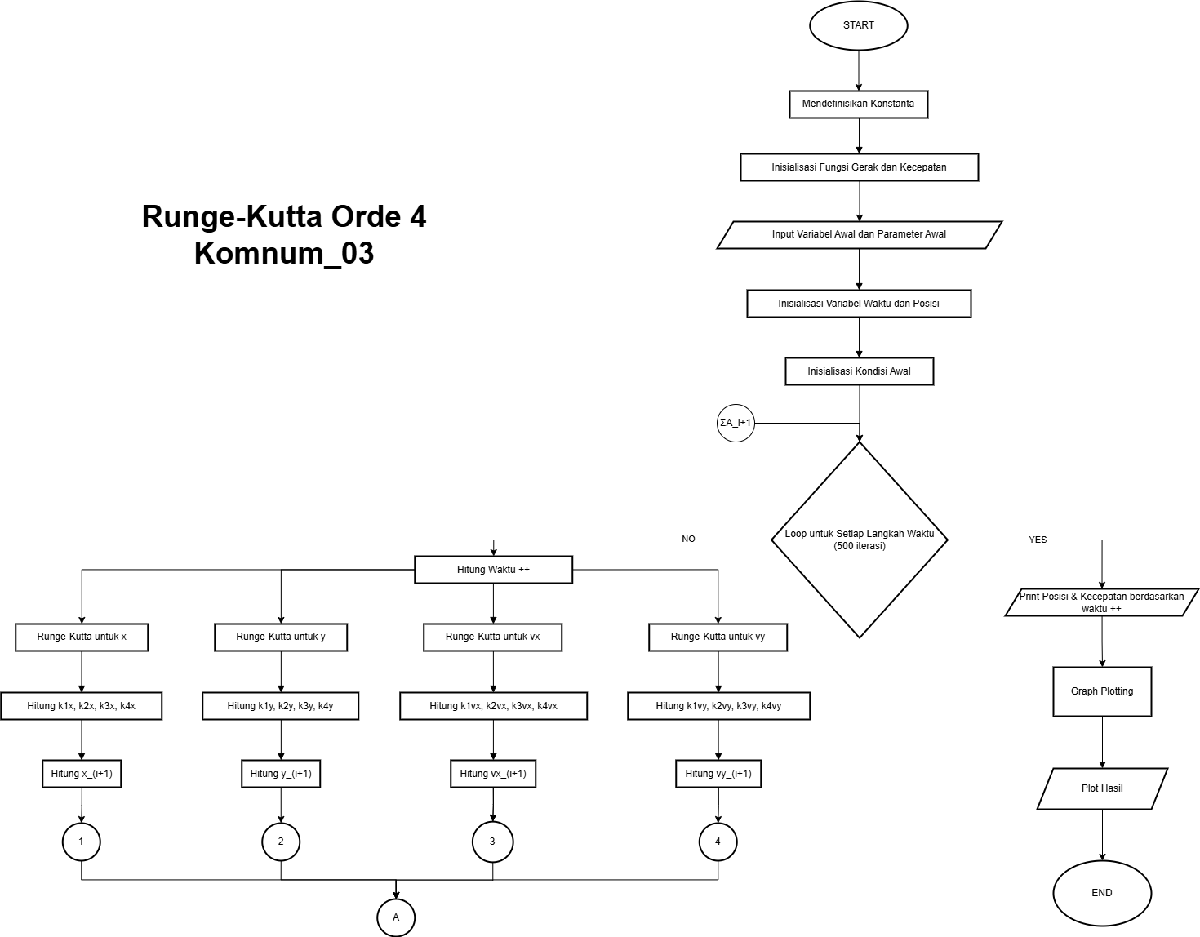

[Link Draw.Io Kelompok 03](https://drive.google.com/file/d/1R6QXScU4khUIaXGM4U5_2EcArdHHoI4Z/view?usp=sharing)

**PERAN ANGGOTA**

Kami mengerjakan dengan bersama-sama melalui aplikasi online. Namun untuk penanggung jawab memastikan bagian masing-masing beroperasi adalah:

1. Julian Krisyairazy - ODE Flowchart & Coding

2. Daffa Arbika - ODE Coding & Flowchart

3. Fauzan Gusri - ODE LaTeX & Coding

4. Annysa Hana Naadhirah - Integrasi Flowchart & Analisis Problem

5. Alvin Hadar - Integrasi Flowchart & LaTeX

6. Fauzan Chiryl - Integrasi flowchart 

7. Farhan Nur Ardianto - Analisis problem & Coding

8. Fadel Achmad - Integrasi Coding & LaTeX